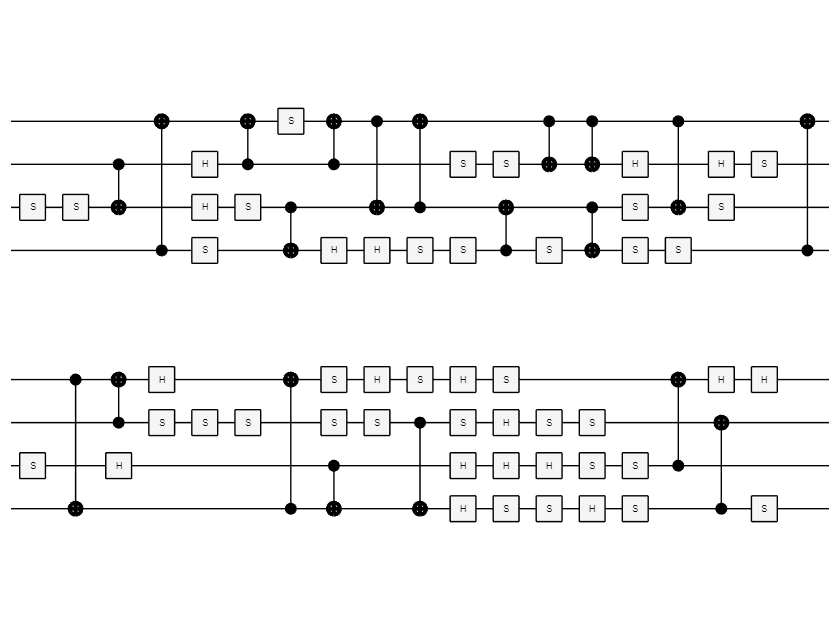

nQubits = 4;
numCliffords = 1;
% Generate a random Clifford circuit
CliffordSet = generate_unique_cliffords(nQubits, numCliffords);
randomClifford = CliffordSet{1};
%ig = initGate(1:2, "10");
gates = [randomClifford];
C = quantumCircuit(gates);
plot(C);

% Apply decryption (reverse order + inverse S)
DecryptedCircuit = decrypt_clifford(CliffordSet{1}); 

  71×1 SimpleGate array with gates:

       Id   Gate   Control   Target
       1    s                4     
       2    cx     4         2     
       3    h                1     
       4    h                1     
       5    cx     3         1     
       6    s                4     
       7    h                4     
       8    s                1     
       9    h                1     
       10   s                2     
       11   s                3     
       12   s                2     
       13   h                2     
       14   s                3     
       15   s                4     
       16   s                4     
       17   s                1     
       18   h                3     
       19   h                4     
       20   s                2     
       21   h                3     
       22   h       

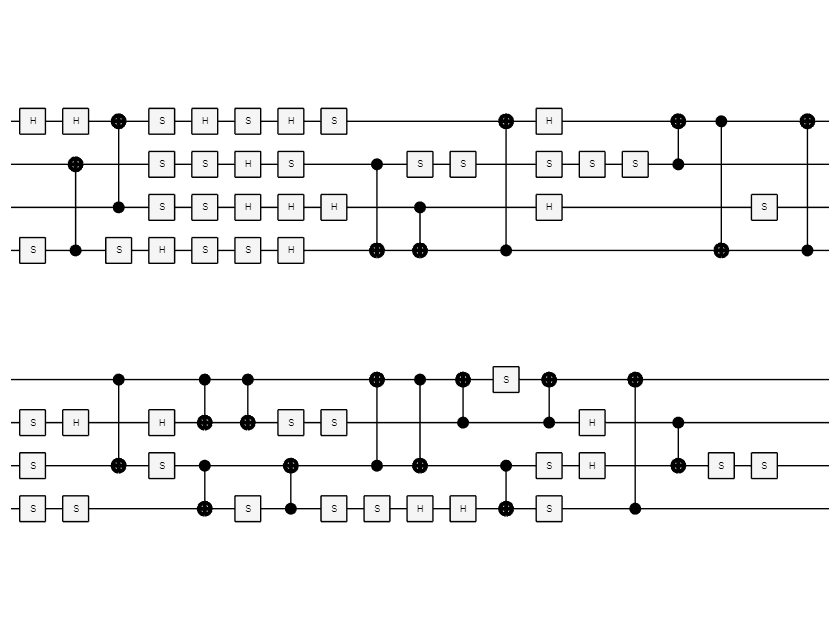

randomClifford = DecryptedCircuit;
%ig = initGate(1:3, "101");
gates = [randomClifford];
D = quantumCircuit(gates);
plot(D);

codeword = ["1001","0010","1100","1111"];
states = [];
for i = 1:length(codeword)
    disp(codeword(i));
    s = simulate(C,codeword(i));
    disp(formula(s));
    t = simulate(D,s);
    disp(formula(t));
end

1001


(-0.25+0.25i) * |0000> +
(-0.25+0.25i) * |0011> +
(0.25-0.25i)  * |0100> +
(-0.25+0.25i) * |0111> +
(-0.25+0.25i) * |1000> +
(-0.25+0.25i) * |1011> +
(-0.25+0.25i) * |1100> +
(0.25-0.25i)  * |1111>


(0-1i) * |1001>


0010


(-0.25-0.25i) * |0001> +
(-0.25-0.25i) * |0010> +
(0.25+0.25i)  * |0101> +
(-0.25-0.25i) * |0110> +
(-0.25-0.25i) * |1001> +
(-0.25-0.25i) * |1010> +
(-0.25-0.25i) * |1101> +
(0.25+0.25i)  * |1110>


(0+1i) * |0010>


1100


(0.25+0.25i)  * |0001> +
(0.25+0.25i)  * |0010> +
(0.25+0.25i)  * |0101> +
(-0.25-0.25i) * |0110> +
(-0.25-0.25i) * |1001> +
(-0.25-0.25i) * |1010> +
(0.25+0.25i)  * |1101> +
(-0.25-0.25i) * |1110>


(0+1i) * |1100>


1111


(0.25-0.25i)  * |0000> +
(-0.25+0.25i) * |0011> +
(-0.25+0.25i) * |0100> +
(-0.25+0.25i) * |0111> +
(-0.25+0.25i) * |1000> +
(0.25-0.25i)  * |1011> +
(-0.25+0.25i) * |1100> +
(-0.25+0.25i) * |1111>


(0-1i) * |1111>






%%%Testing the reversing of the permutation%%%
% Define the initial codeword
codeword = ['D', 'O', 'G', 'S','C','H','I','L','L','I','N','!'];

% Define the permutation
p = randperm(length(codeword)); 
% Function to generate swap gates
swapList = permutationToSwapGates(p);
% Apply the swap gates sequentially
for i = 1:size(swapList, 1)
    codeword = applySwapGate(codeword, swapList(i).TargetQubits(1), swapList(i).TargetQubits(2));
end

% Display the final codeword
disp('Final codeword:');

Final codeword:


disp(codeword);

IHOC!DGNSLLI


%Undo the permutation
%inv = invert_permutation(p);
%swapList_inv = permutationToSwapGates(p);
% **Apply swaps in reverse order to undo the permutation**
for i = size(swapList, 1):-1:1
    codeword = applySwapGate(codeword, swapList(i).TargetQubits(1), swapList(i).TargetQubits(2));
end

disp('Recovered codeword:');

Recovered codeword:


disp(codeword);

DOGSCHILLIN!



% Function to simulate a swap gate for testing
function swappedWord = applySwapGate(codeword, i, j)
    swappedWord = codeword;
    temp = swappedWord(i);
    swappedWord(i) = swappedWord(j);
    swappedWord(j) = temp;
end
function permutationInverse = invert_permutation(p)
    n = length(p);
    %Create an array of the same size as the original permutation
    permutationInverse = zeros(1, n);
    %to invert a mapping of x to y we do y to x
    for y = 1:n
        x = p(y); %x is at position y
        permutationInverse(x) = y; %put y at position x
    end
end

function DecryptedClifford = decrypt_clifford(EncryptedClifford)
    % Reverse the gate order
    DecryptedClifford = flipud(EncryptedClifford);
    disp(DecryptedClifford)
    % Loop through each gate and modify it if needed
    for i = 1:length(DecryptedClifford)
        gate = DecryptedClifford(i); %Get the current gate
        if contains(gate.Type, "sGate")
            % Replace "sGate(X)" with "sdagGate(X)" for inverse
            target = extractBetween(gate, "sGate(", ")"); % Extract qubit index
            DecryptedClifford{i} = sprintf("sdagGate(%s)", target{1});
        end
        % hGate and cxGate remain unchanged
    end
end

f

% function to turn a qubit permutation into a set of transpositions to fit
% it into the swapGate function
function swapList = permutationToSwapGates(p)
    n = length(p);
    visited = false(1, n);
    swapList = [];
    for i = 1:n
       if ~visited(i)
           cycle = [];
           j = i;
           while ~visited(j)
               visited(j) = true;
               cycle(end+1) = j;
               j = p(j);
           end
           if length(cycle) > 1
               for k = length(cycle):-1:2
                   newGate = swapGate(cycle(1), cycle(k));
                   swapList = [swapList; newGate];
               end
           end
       end
    end
end

Generate an array of X clifford operators by combining known clifford operators

function CliffordSet = generate_unique_cliffords(nQubits, d1)
   CliffordSet = cell(1, d1);
  
   for i = 1:d1
       qc = quantumCircuit(nQubits);
       newClifford = [];
       switch nQubits
           case 2
               gatecount = 1:randi([2, 3]);
           case 3
               gatecount = 1:randi([3, 50]);
           case 4
               gatecount = 1:randi([3, 110]);
           case 5
               gatecount = 1:randi([3, 200]);
           case 6
               gatecount = 1:randi([3, 300]);
       end
      
       % Generate random Clifford explicitly
       for gateIdx = gatecount
           gateType = randi(3);
           targetQubit = randi(nQubits);
           switch gateType
               case 1, g = hGate(targetQubit);
               case 2, g = sGate(targetQubit);
               case 3
                   control = randi(nQubits);
                   while control == targetQubit
                       control = randi(nQubits);
                   end
                   g = cxGate(control, targetQubit);
           end
           newClifford = [newClifford; g];
       end
       CliffordSet{i} = newClifford;
   end
end